Aula prática   14/03/2023

ASSUNTO: MHORNER E POLYVAL

%Interface01 para testar o MHorner e o polyval do Matlab
%   12/03/15 - ArménioCorreia .: armenioc@isec.pt 

clc
clear

disp('-------------------------POLINÓMIOS-------------------------------');

-------------------------POLINÓMIOS-------------------------------


disp('----Método de Horner para a fórmula dos parênteis encaixados------');

----Método de Horner para a fórmula dos parênteis encaixados------


disp('----Polyval do Matlab---------------------------------------------');

----Polyval do Matlab---------------------------------------------


disp('                                                                  ');

a = [0,0,1];
x = -1:0.1:1;
yHorner=MHorner(a,x);

a = a(end:-1:1);
ypolyval=polyval(a,x);

disp('Tabela com resultados');

Tabela com resultados


A =[x.',yHorner.',ypolyval.'];
fprintf('\n\t x\t\t y_Horner\t y_polyval\n')


	 x		 y_Horner	 y_polyval


disp(A)

   -1.0000    1.0000    1.0000
   -0.9000    0.8100    0.8100
   -0.8000    0.6400    0.6400
   -0.7000    0.4900    0.4900
   -0.6000    0.3600    0.3600
   -0.5000    0.2500    0.2500
   -0.4000    0.1600    0.1600
   -0.3000    0.0900    0.0900
   -0.2000    0.0400    0.0400
   -0.1000    0.0100    0.0100
         0         0         0
    0.1000    0.0100    0.0100
    0.2000    0.0400    0.0400
    0.3000    0.0900    0.0900
    0.4000    0.1600    0.1600
    0.5000    0.2500    0.2500
    0.6000    0.3600    0.3600
    0.7000    0.4900    0.4900
    0.8000    0.6400    0.6400
    0.9000    0.8100    0.8100
    1.0000    1.0000    1.0000



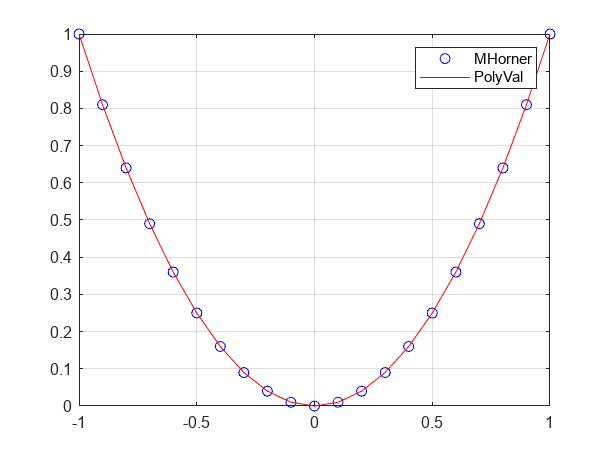


plot(x,yHorner,'ob')
hold on
plot(x,ypolyval,'r')
hold off
grid on
legend('MHorner','PolyVal')

shg

%help table
%doc table

tabelaResultados = array2table(A,"VariableNames",["X","YHORNER","YPOLYVAL"])

tabelaResultados = 21×3 table
     X      YHORNER    YPOLYVAL
    ____    _______    ________

      -1        1           1  
    -0.9     0.81        0.81  
    -0.8     0.64        0.64  
    -0.7     0.49        0.49  
    -0.6     0.36        0.36  
    -0.5     0.25        0.25  
    -0.4     0.16        0.16  
    -0.3     0.09        0.09  
    -0.2     0.04        0.04  
    -0.1     0.01        0.01  
       0        0           0  
     0.1     0.01        0.01  
     0.2     0.04        0.04  
     0.3     0.09        0.09  
     0.4     0.16        0.16  
     0.5     0.25        0.25  



writematrix(A,"ficheiro1MHorner.xlsx")
writetable(tabelaResultados,"ficheiro2MHorner.xlsx")
winopen("ficheiro1MHorner.xlsx")
open("ficheiro2MHorner.xlsx")

